## Create a parallel equalizer

eq = graphicEQ('Structure','Parallel')

eq =   graphicEQ with properties:

       EQOrder: 2
     Bandwidth: '1 octave'
     Structure: 'Parallel'
         Gains: [0 0 0 0 0 0 0 0 0 0]
    SampleRate: 44100


Configure the object you created to boost low and high frequencies

eq.Gains = [-19, -19, -18, -17, -16, -14, -9, 0, 16, 16]

eq =   graphicEQ with properties:

       EQOrder: 2
     Bandwidth: '1 octave'
     Structure: 'Parallel'
         Gains: [-19 -19 -18 -17 -16 -14 -9 0 16 16]
    SampleRate: 44100


Call `visualize` to view the magnitude response of the equalizer design.

visualize(eq)

test the equalizer implemented in graphicEQ using Audio Test Bench.

%audioTestBench(eq)

## Try cascade configuration

cascadeGraphicEQ = graphicEQ;
visualize(cascadeGraphicEQ)

cascadeGraphicEQ.Gains = [-19, -19, -18, -17, -16, -14, -9, 0, 16, 16, 16]

cascadeGraphicEQ =   graphicEQ with properties:

       EQOrder: 2
     Bandwidth: '1 octave'
     Structure: 'Cascade'
         Gains: [-19 -19 -18 -17 -16 -14 -9 0 16 16]
    SampleRate: 44100


audioTestBench(cascadeGraphicEQ)

The drawback of cascade design is that the coefficients of a biquad stage need to be redesigned whenever the corresponding gain changes. This isn't needed for the parallel implementation because gain is just a multiplier to each parallel branch. A parallel connection of bandpass filters also avoids accumulating phase errors and quantization noise found in the cascade.

## Fractional Octave Bandwidth

The `graphicEQ` object supports `1 octave`, `2/3 octave`, and `1/3 octave` bandwidths. Reducing the bandwidth of individual filters allows you finer control over frequency response. To verify this, set the gains to boost mid frequencies, similar to a *pop* preset.

sut = graphicEQ('Structure','Parallel');
sut.Bandwidth = '1/3 octave';
% sut.Gains = [-20,-20,-20,-20,-20,-20,-20,-20,-20, ...
%     -20,-20,-20,-20,-19,-18,-13,-10,-8,-5,-2,-1.2,-1,0,4,5,10, ...
%     20,16,12,-10];
% sut.Gains1 = -20;
% sut.Gains2 = -20;
% sut.Gains3 = -20;
% sut.Gains4 = -20;
% sut.Gains5 = -20;
% sut.Gains6 = -20;
% sut.Gains7 = -20;
% sut.Gains8 = -20;
% sut.Gains9 = -20;
% sut.Gains10 = -20;
% sut.Gains11 = -20;
% sut.Gains12 = -20;
% sut.Gains13 = -20;
% sut.Gains14 = -19;
% sut.Gains15 = -19;
% sut.Gains16 = -17.2468;
% sut.Gains17 = -15.4805;
% sut.Gains18 = -14.3377;
% sut.Gains19 = -13.9221;
% sut.Gains20 = -11.1169;
% sut.Gains21 = -8.31169;
% sut.Gains22 = -5.09091;
% sut.Gains23 = -2.80519;
% sut.Gains24 = 2.07792;
% sut.Gains25 = 10.0779;
% sut.Gains26 = 15.2727;
% sut.Gains27 = 18.9091;
% sut.Gains28 = 14.7533;
% sut.Gains29 = 6.23377;
% sut.Gains30 = -0.103895;
%sut.SampleRate = fileReader.SampleRate;
%----------------------------------------
%sut.Gains1 = -20;
%sut.Gains2 = -20;
%sut.Gains3 = -20;
%sut.Gains4 = -20;
%sut.Gains5 = -20;
%sut.Gains6 = -20;
%sut.Gains7 = -20;
%sut.Gains8 = -20;
%sut.Gains9 = -20;
%sut.Gains10 = -20;
%sut.Gains11 = -20;
%sut.Gains12 = -20;
%sut.Gains13 = -20;
%sut.Gains14 = -20;
%sut.Gains15 = -19.3247;
%sut.Gains16 = -19.3247;
%sut.Gains17 = -20;
%sut.Gains18 = -19.6883;
%sut.Gains19 = -20;
%sut.Gains20 = -18.7532;
%sut.Gains21 = -17.0909;
%sut.Gains22 = -14.2857;
%sut.Gains23 = -11.6883;
%sut.Gains24 = -8.15584;
%sut.Gains25 = -3.8961;
%sut.Gains26 = 1.61039;
%sut.Gains28 = 5.66234;
%sut.Gains29 = 0.987018;
%sut.Gains30 = -10.0779;


sut.Gains1 = -20;
sut.Gains2 = -20;
sut.Gains3 = -20;
sut.Gains4 = -20;
sut.Gains5 = -20;
sut.Gains6 = -20;
sut.Gains7 = -20;
sut.Gains8 = -20;
sut.Gains9 = -20;
sut.Gains10 = -20;
sut.Gains11 = -20;
sut.Gains12 = -20;
sut.Gains13 = -20;
sut.Gains14 = -20;
sut.Gains15 = -20;
sut.Gains16 = -20;
sut.Gains17 = -20;
sut.Gains18 = -19.6883;
sut.Gains19 = -20;
sut.Gains20 = -19.013;
sut.Gains21 = -16.9351;
sut.Gains22 = -6.75325;
sut.Gains23 = -0.207789;
sut.Gains24 = 2.7013;
sut.Gains25 = 6.12987;
sut.Gains26 = 10.0779;
sut.Gains27 = 11.4286;
sut.Gains28 = 10.2857;
sut.Gains29 = 6.33766;
sut.Gains30 = 3.01299;
%sut
%visualize(sut)

test the equalizer implemented in graphicEQ using Audio Test Bench.

audioTestBench(sut)

Error using audio.testbench.internal.AppLauncher.openApp (line 114)
Unable to open multiple instances of Audio Test Bench. Close existing instance before opening another.

Error in audioTestBench (line 70)
    audio.testbench.internal.AppLauncher.openApp(varargin{1},inputname(1));

twoThirdOctaveGraphicEQ = graphicEQ

twoThirdOctaveGraphicEQ =   graphicEQ with properties:

       EQOrder: 2
     Bandwidth: '1 octave'
     Structure: 'Cascade'
         Gains: [0 0 0 0 0 0 0 0 0 0]
    SampleRate: 44100


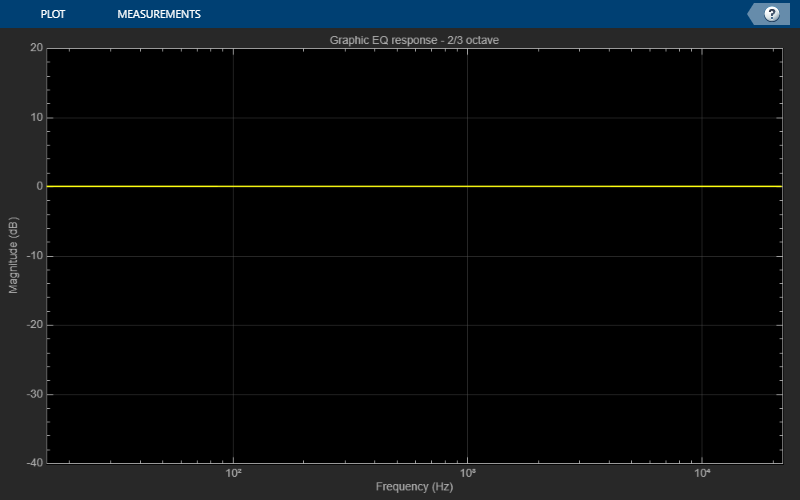

twoThirdOctaveGraphicEQ.Bandwidth = '2/3 octave';
% twoThirdOctaveGraphicEQ.Gains = [-20,-20,-20,-20,-20,-20,-20,-20,-20, ...
%     -20,-20,-20,-20,-19,-18,-13,-10,-8,-5,-2,-1.2,-1,0,4,5,10, ...
%     18,16,12,-6];
visualize(twoThirdOctaveGraphicEQ)

audioTestBench(twoThirdOctaveGraphicEQ)

Error using audio.testbench.internal.AppLauncher.openApp (line 114)
Unable to open multiple instances of Audio Test Bench. Close existing instance before opening another.

Error in audioTestBench (line 70)
    audio.testbench.internal.AppLauncher.openApp(varargin{1},inputname(1));